Identifikovane polynomy

pGain = [-7.74558355399971e-09 7.92523655765039e-06 -0.00291980737503381 0.463728547328537 -23.1386227555553];
pT = [1.10661505286941e-07 -5.48243874702451e-05 0.00740611980939077 -0.00882197108389277];

n0 = 1;%index prveho suboru
n = 6;%pocet suborov
m = 19;%predpoklad pocet derivacii vstupu (zmeny vstupu)
w = 80;%Pocet dat povaz ako ustalene

dataStore = zeros((m)*w,n+2);
for i=1:n
    fileName = ['./../TP-PlainData/allSig_log_prev_mer',num2str((n0-1)+i),'_up.csv'];
    dt = csvread(fileName);
    diffVal = diff(dt(2:end,2));
    ids = find(or(diffVal > 0,diffVal < 0));
    ln = size(ids,1);
    if ln == m
        ln = size(dt,1);
        id = ids;
        for j=1:m
            if i == 1
                dataStore(1+w*(j-1):w*j,1) = dt(id(j):id(j)+w-1,1);
                dataStore(1+w*(j-1):w*j,2) = dt(id(j):id(j)+w-1,2);
            end
            dataStore(1+w*(j-1):w*j,i+2) = dt(id(j):id(j)+w-1,3);
        end
    end
end

sim_u = dataStore(:,1:2);

out = sim("model.slx");

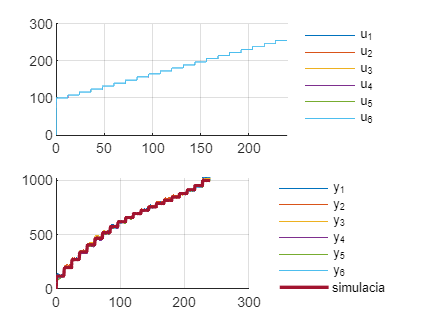

figure;
for i=n0:n0+n-1
    fileName = ['./../TP-PlainData/allSig_log_prev_mer',num2str(i),'_up.csv'];
    dt = csvread(fileName);
    subplot(2,1,1);
    txt = ['u_',num2str(i)];
    hold on;
    plot(dt(:,1),dt(:,2),'DisplayName',txt);
    hold off;
    legend('Location','bestoutside'); grid on; legend boxoff;
    subplot(2,1,2);
    txt = ['y_',num2str(i)];
    hold on;
    plot(dt(:,1),dt(:,3),'DisplayName',txt);
    hold off;
end
subplot(2,1,2);
hold on;
plot(out.y.Time,out.y.Data,'DisplayName','simulacia','LineWidth',2);
hold off;
legend('Location','bestoutside'); grid on; legend boxoff;